help eps

 eps  Spacing of floating point numbers.
    D = eps(X), is the positive distance from ABS(X) to the next larger in
    magnitude floating point number of the same precision as X.
    X may be either double precision or single precision.
    For all X, eps(X) is equal to eps(ABS(X)).
 
    eps, with no arguments, is the distance from 1.0 to the next larger double
    precision number, that is eps with no arguments returns 2^(-52).
 
    eps('double') is the same as eps, or eps(1.0).
    eps('single') is the same as eps(single(1.0)), or single(2^-23).
 
    Except for numbers whose absolute value is smaller than REALMIN,
    if 2^E <= ABS(X) < 2^(E+1), then
       eps(X) returns 2^(E-23) if ISA(X,'single')
       eps(X) returns 2^(E-52) if ISA(X,'double')
 
    For all 


eps

ans = 2.2204e-16

eps(10)

ans = 1.7764e-15

eps(single(10))

ans = single
9.5367e-07


help realmax

 realmax Largest finite floating point number.
    realmax returns the largest finite floating point number in IEEE double
    precision.
 
    realmax('double') is the same as realmax.
 
    realmax('single') returns the largest finite floating point number in
    IEEE single precision.
 
    See also eps, realmin, intmax.

    Documentation for realmax



realmax

ans = 1.7977e+308

realmax('single')

ans = single
3.4028e+38


realmin

ans = 2.2251e-308

realmin('single')

ans = single
1.1755e-38


S1 =  1 - 0.4 - 0.3 - 0.2 - 0.1

S1 = -2.7756e-17

S2 =  1 - (0.4 + 0.3 + 0.2 + 0.1)

S2 = 1.1102e-16

S3 = 1 - (0.4 + 0.3) - 0.2 - 0.1

S3 = 2.7756e-17

S4 = 1 - (0.4 + 0.3) - (0.2 + 0.1)

S4 = 0


help fi

 fi     Fixed-point numeric object
 
    Syntax:
      a = fi
      a = fi(v)
      a = fi(v, s)
      a = fi(v, s, w)
      a = fi(v, s, w, f)
      a = fi(v, s, w, slope, bias)
      a = fi(v, s, w, slopeadjustmentfactor, fixedexponent, bias)
      a = fi(v, T)
      a = fi(v, T, F)
      a = fi(v, F)
      a = fi(v, s, F)
      a = fi(v, s, w, F)
      a = fi(v, s, w, f, F)
      a = fi(v, s, w, slope, bias, F)
      a = fi(v, s, w, slopeadjustmentfactor, fixedexponent, bias, F) 
      a = fi(..., property1, value1, ...)
      a = fi(property1, value1, ...)
 
    Description:
      fi is the default constructor and returns a signed fixed-point object
      with no value, 16-bit word length, and 15-bit fraction length.
 
      fi(v) returns a signed fixed-point object with value v, 16-bit
      word length, and best-precision fraction length. Best-precision
      is when the fraction length is set automatically to accommodate the
      value v for the given word leng

help bin

--- help for varbacktest/bin ---

  bin Binomial test for Value-at-Risk (VaR) backtesting.
 
  Syntax:
 
    TestResults = bin(vbt)
    TestResults = bin(vbt,param1,val1,...)
 
  Description:
 
    bin performs a binomial test to assess if the number of failures is
    consistent with the VaR confidence level. The binomial test in this
    implementation is based on a normal approximation to the binomial
    distribution; see notes for details.
 
  Input arguments:
 
    vbt - VARBACKTEST object.
 
  Optional Input Parameter Name/Value Pairs:
 
    'TestLevel'  Numeric value strictly between 0 and 1, to indicate the
                 desired test confidence level. Default value is 0.95.
 
  Output:
 
    TestResults - Table of results where the rows correspond to all
        combinations of portfolio ID, VaR ID, and VaR level to be tested.
        The columns correspond to the following information:
 
        'PortfolioID'   Portfolio I


x1 = fi(0.5, 1, 4, 3)

x1 =     0.5000

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 4
        FractionLength: 3

x1bin = bin(x1)

x1bin = '0100'


x2 = fi(-0.5, 1, 4, 3)

x2 =    -0.5000

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 4
        FractionLength: 3

x2bin = bin(x2)

x2bin = '1100'

I = 5;
Rp = 0.05;
As = 40;
f = [0.1 0.2];
a = [I 0];
d1 = (1-db2mag(-Rp*I))/(1+db2mag(-Rp*I));
d2 = db2mag(-As)*(1+d1);
d = [d1 d2];
[M, fo, ao, W] = firpmord(f,a,d)

M = 46

fo =          0
    0.1000
    0.2000
    1.0000


ao =      5
     5
     0
     0


W =     3.5246
    1.0000


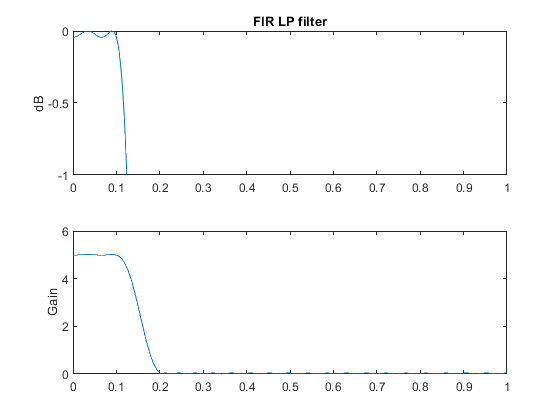

h = firpm(M, fo, ao, W);
[db, mag, pha, grd, w] = freqz_m(h, [1]);
figure;
subplot(2,1,1);
plot(w/pi,db);
title('FIR LP filter')
ylabel('dB')
axis([0 1 -1 0])
subplot(2,1,2)
plot(w/pi,mag);
ylabel('Gain')

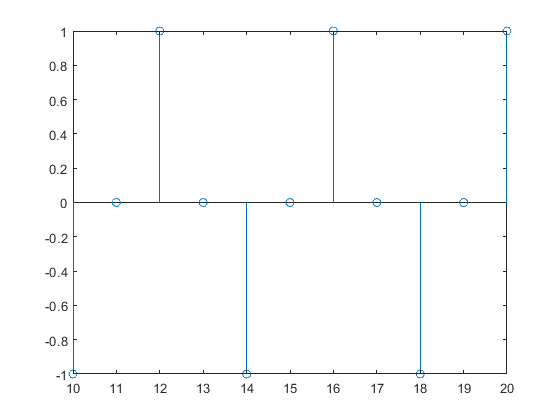


n = 0:50;
x = cos(0.5*pi*n);
y = upfirdn(x,h,I);
figure
stem(n,x);
axis([10 20 -1 1])

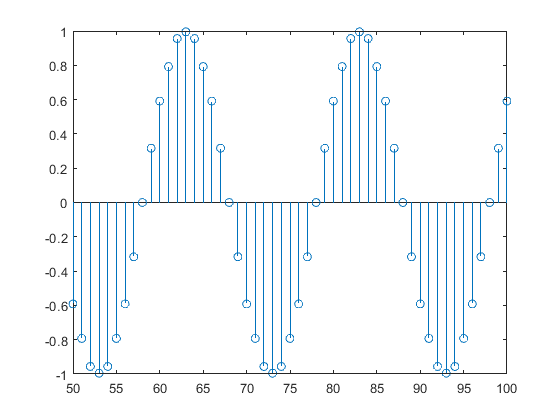

figure
stem(0:length(y)-1,y)
axis([50 100 -1 1])

Rp = 0.1;
As = 30;
ws = 0.5*pi;
wp = 0.45*pi;
M = ceil((As - 7.95)/(2.285*(ws-wp)) + 1)

M = 63

M = M + 50

M = 113

hd = ideal_lp((ws+wp)/2,M);
beta = 0.5842*(As - 21)^0.4 + 0.07886*(As - 21)

beta = 2.1166

beta = 4

beta = 4

wk = kaiser(M,beta)';
h = hd .* wk;
[db,mag,pha,grd,w] = freqz_m(h,[1]); delta_w = 2*pi/1000;
Rp = -(min(db(1:1:wp/delta_w+1))) % Actual Passband Ripple 

Rp = 0.0716

As = -round(max(db(ws/delta_w+1:1:501))) % Min Stopband attenuation 

As = 46

figure;
subplot(2,1,1);
plot(w/pi,db);
length(w/pi)

ans = 501

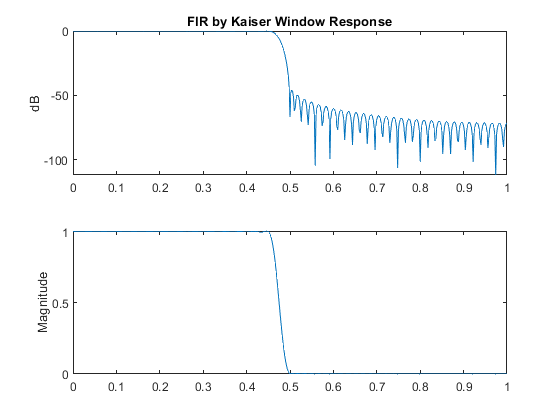

ylabel('dB');
title('FIR by Kaiser Window Response')
subplot(2,1,2);
plot(w/pi, mag);
ylabel('Magnitude')

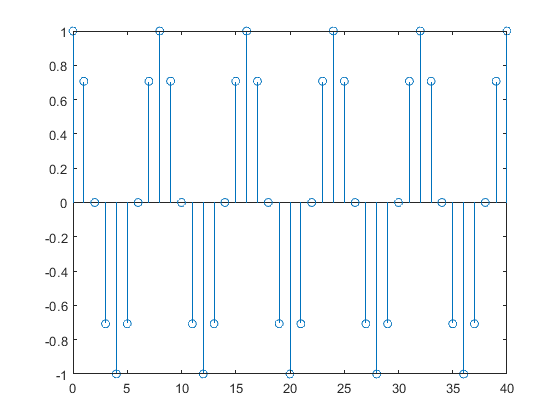


D = 4;
n = 0:500;
x = cos(pi*n/4);
y = upfirdn(x,h,1,D);
figure
stem(n,x);
axis([0 40 -1 1])

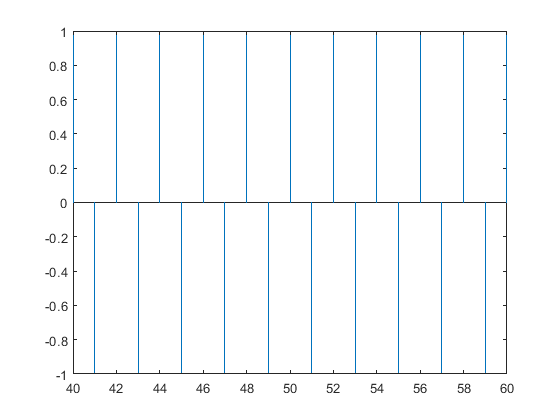

figure
stem(0:length(y)-1,y)
axis([40 60 -1 1])